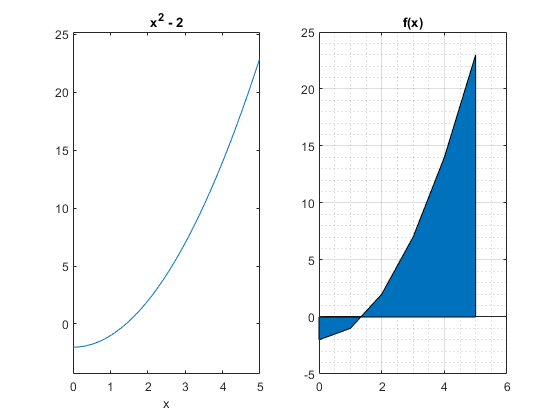

%% User inputs
clear all;clc  
a =0; %input("Please input a: ");
b =5; %input("Please input b: ");
n = 4;%input("Please input the number of segments: ");
n2 = 0;

% Lab requirement to use even segments for simpsons rule
% Keep asking the user for an even value to be used
if( mod(n,2) == 1 )
    n2 = input("Please input an even n for Simpson's Rule: \n");
    while(mod(n2, 2) == 1 )
        n2 = input("Please input an even n for Simpson's Rule: \n");
    end
end





%% Coefficients

% The while loop will make a vector or an array of values that were 
% inputted by the user to create a function f(x)
% amount = input("How many values will you be inserting?: ");
% c = 1;
% coe = [1:amount];
% while c-1 ~= amount
%     p = input("Please enter c value: ");
%     coe(c)= p;
%     c = c + 1;  
% end 
coe = [1 0 -2];


%Sending the value to the function
fx = f(coe); % Horner's Algorithm to show the function f(x)
%% Plots
graph(fx, a , b);



%% Calculations for Trapezoid Rule
y = matlabFunction(fx); % show the function in a nicer format

segments = (b-a)/n;
parts = [a:segments:b];

trapRule = segments/2;
func = zeros(1,length(parts),'sym');

i = 1;z = 1;
while i <= length(parts)
    func(i) = y(parts(z));
    i = i + 1; z = z + 1;
end

newFunc = zeros(1,length(parts),'sym');
newFunc(1) = func(1);
newFunc(length(func)) = func(length(func));
for v = 2 : length(func)-1
    newFunc(v) = 2*func(v);
end


fx

$$fx = x^{2}-2$$

integralFxApproximation = integral(y, a, b)

integralFxApproximation = 31.6667

fprintf("\nTrapezoid Rule: \n");


Trapezoid Rule: 


trapezoidResults = eval(trapRule * sum(newFunc))

trapezoidResults = 32.9688

trapezoidEt = trapezoidResults - integralFxApproximation

trapezoidEt = 1.3021

absRelativeError = abs(trapezoidEt/integralFxApproximation)

absRelativeError = 0.0411


fprintf("Simpson's Rule: \n");

Simpson's Rule: 



%% Calculations for Simpson's Rule
g = matlabFunction(fx); % show the function in a nicer format

delta = (b-a)/n;
simpParts = [a:segments:b];

simpRule = delta/3;
simpFunc = zeros(1,length(simpParts),'sym');

q = 1;w = 1;
while q <= length(simpParts)
    simpFunc(q) = y(simpParts(w));
    q = q + 1; w = w + 1;
end


newSimpFunc = zeros(1,length(simpParts),'sym');
newSimpFunc(1) = simpFunc(1);
newSimpFunc(length(simpFunc)) = simpFunc(length(simpFunc));

for k = 2 : length(simpFunc)-1
    if( mod(k,2) == 0)
        newSimpFunc(k) = 4*simpFunc(k);
    else
        newSimpFunc(k) = 2*simpFunc(k);
    end
end

simpResults = eval(simpRule * sum(newSimpFunc))

simpResults = 31.6667

simpEt = simpResults - integralFxApproximation

simpEt = -3.5527e-15

absRelError = abs(simpEt/integralFxApproximation)

absRelError = 1.1219e-16



%% Horner's Algorithm evaluated

function y = f(coef) 
    syms x; 
    n = length(coef);
    results = coef(1);
    for j = 2 : n % starts the for loop
        results = results*x + coef(j);
    end % ends the for loop
   
    %making it look nice
    pw = length(coef)-1;
    str = zeros(1,length(coef),'sym');
    
    i = 1; 
    while i <= length(coef)
        str(i) = (coef(i)*(x^pw));
        i = i + 1; 
        pw = pw - 1;
    end
       
    y = results;% results saved to y 
end

%% Graph the Function
function graph(func, a, b)
    figure(1);
    x = a:b;
    hold on;
    subplot(1,2,1);
    ezplot(func,[a,b]);
    subplot(1,2,2);
    area(x, eval(func));
    title('f(x)')
    grid on;
    grid minor;
    hold off;
    
end
